# Homework 5

**Name:** YOUR NAME HERE

**Due Date: **

clear, clc

## Problem #1 - Comparing Runge-Kutta methods

**SETUP FOR PROBLEM**

dydt = @(x,y) (38*x.^2+32*x+47)./(8*y.^2);
x0 = 1.5;
xf = 5.5;
y0 = 2.9;


**a) Analytically**

syms y(x)
ode = diff(y,x) == (38*x.^2+32*x+47)./(8*y.^2);
cond = y(x0) == y0;
yExact(x) = dsolve(ode, cond)

$$yExact(x) = \frac{{\left(38\,x^{3}+48\,x^{2}+141\,x-\frac{126319}{500}\right)}^{1/3}}{2}$$

**b) Using Euler's method**

h1 = 1;
h2 = .5;
x_vals1 = x0:h1:xf;
x_vals2 = x0:h2:xf;

y_Euler1 = zeros(size(x_vals1));
y_Euler1(1) = y0;
for i = 1:(length(y_Euler1)-1)
    phi = dydt(x_vals1(i), y_Euler1(i));
    y_Euler1(i+1) = y_Euler1(i) + phi*h1;
end

y_Euler2 = zeros(size(x_vals2));
y_Euler2(1) = y0;
for i = 1:(length(y_Euler2)-1)
    phi = dydt(x_vals2(i), y_Euler2(i));
    y_Euler2(i+1) = y_Euler2(i) + phi*h2;
end

**c) Using midpoint method**

h = 1;
x_vals = x0:h:xf;
y_Mid = zeros(size(x_vals));
y_Mid(1) = y0;
for i = 1:(length(y_Mid)-1)
    slope = dydt(x_vals(i), y_Mid(i));
    midpoint = y_Mid(i) + slope*h/2;
    phi = dydt((x_vals(i)+h/2), midpoint);
    y_Mid(i+1) = y_Mid(i) + phi*h;
end

**d) Using 4th-order Runge-Kutta**

[xrk4,yrk4] = rk4sys(dydt, [x0, xf], y0, 1)

xrk4 =     1.5000    2.5000    3.5000    4.5000    5.5000


yrk4 =     2.9000
    4.9949
    6.7509
    8.4459
   10.1236


**e) Plot of results**

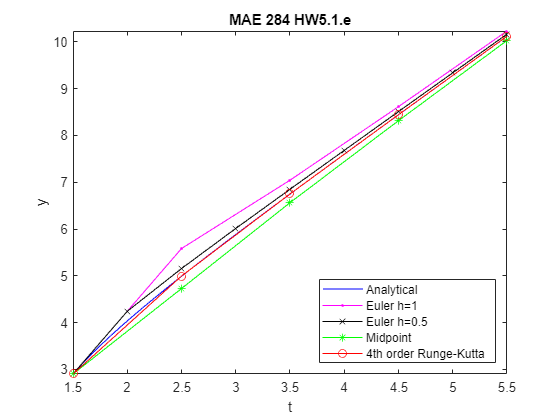

fplot(yExact(x), [x0 xf], "b-")
hold on
plot(x_vals1, y_Euler1, "-m.", x_vals2, y_Euler2, "-kx", x_vals, y_Mid, "-g*", xrk4, yrk4, "-ro")
hold off
xlabel 't'
ylabel 'y'
title 'MAE 284 HW5.1.e'
legend('Analytical', 'Euler h=1', 'Euler h=0.5', 'Midpoint', '4th order Runge-Kutta', 'location','southeast')

## Problem #2 - 4th order Runge-Kutta

**SETUP FOR PROBLEM**

## Problem #3 - Mass-spring-damper system

**SETUP FOR PROBLEM**

**a) Displacement vs. time plot**

**b) Velocity vs. time plot**

## Problem #4 - Euler-Cauchy

**SETUP FOR PROBLEM**

**a) Analytically**

**b) Implicit Euler's**

**c) ode23s**

**d) Plot of solutions**

## Helper functions

### Problem #3 system function